# show ratio slope

clear;
close all;
axlabels = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
pop = 5;
popEI = 3;
sz = 20;
p_base = [0.1184, 0.1552, 0.0846, 0.0629, 0.0323, 0.0000, 0.0076, 0.0000;
          0.1008, 0.1371, 0.0363, 0.0515, 0.0755, 0.0000, 0.0042, 0.0000;
          0.0077, 0.0059, 0.0519, 0.1453, 0.0067, 0.0003, 0.0453, 0.0000;
          0.0691, 0.0029, 0.1093, 0.1597, 0.0033, 0.0000, 0.1057, 0.0000;
          0.1017, 0.0622, 0.0411, 0.0057, 0.0758, 0.3765, 0.0204, 0.0000;
          0.0436, 0.0269, 0.0209, 0.0022, 0.0566, 0.3158, 0.0086, 0.0000;
          0.0156, 0.0066, 0.0211, 0.0166, 0.0572, 0.0197, 0.0401, 0.2252;
          0.0364, 0.0010, 0.0034, 0.0005, 0.0277, 0.0080, 0.0658, 0.1443]; % intracolumn connection probability % [Wagatsuma 2011]
p = [p_base, zeros(8,8); zeros(8,8), p_base];
p(2,9) = 0.1;
p(10,1) = 0.1;
p = repmat(p,[1,1,5]);

## show ratio slope

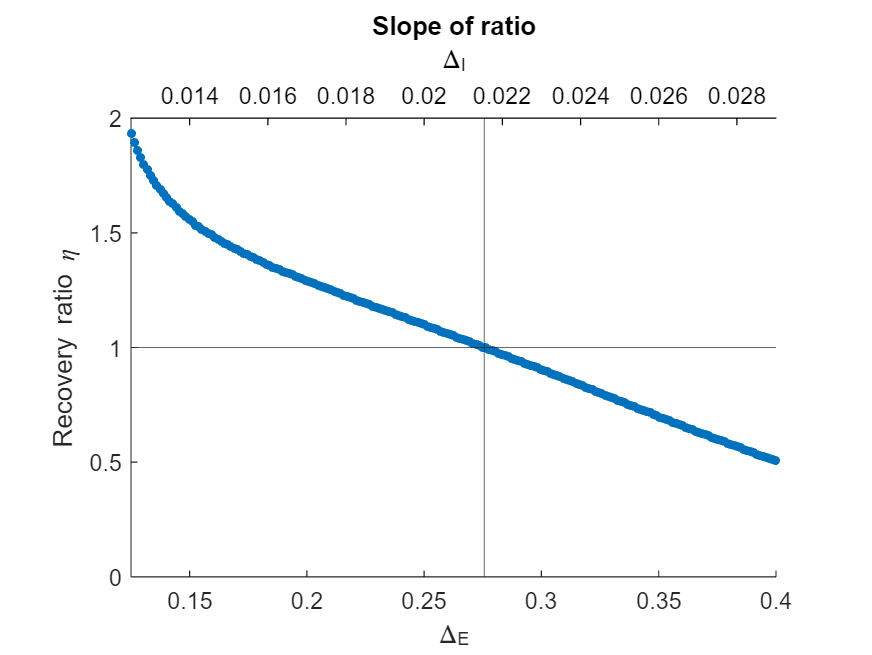

rootFolder = "figure_linSampling_0.02_201/";
startXbottom = 0.125; endXbottom = 0.4;
sz = 15;
% ON-ON
data = readFilename(rootFolder+"agree/*_*_*_*_*_*.png",'%f_%f_%f_%f_%f_%f');
data( all(~data,2), : ) = [];

lowY = 0; highY = 2;
figure();
pos = [0.15 0.12 0.74 0.7];
s = zeros(8,1);
ax1 = axes();

x = data(:,1);
y = data(:,4);
s = scatter(x,y,sz,'filled');

yline(1);
x1 = 0.27487; y1 = 1.0022;
x2 = 0.27625; y2 = 0.9982;
m = (y2 - y1) / (x2 - x1);
b = y1 - m*x1;
oneRatio = (1-b)/m;
xline(oneRatio);

ax1.XLim = [startXbottom endXbottom];
ax1.YLim = [0 2];
% legend(s,axlabels(1:8), 'Location','northwest');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];
xlabel(ax2, '\Delta_{I}');
set(ax2,'Position',pos);

xlabel(ax1, '\Delta_{E}');
ylabel(ax1, "Recovery ratio \eta");
set(ax1,'Position',pos);
title("Slope of ratio");

## EXC, 1L5E in

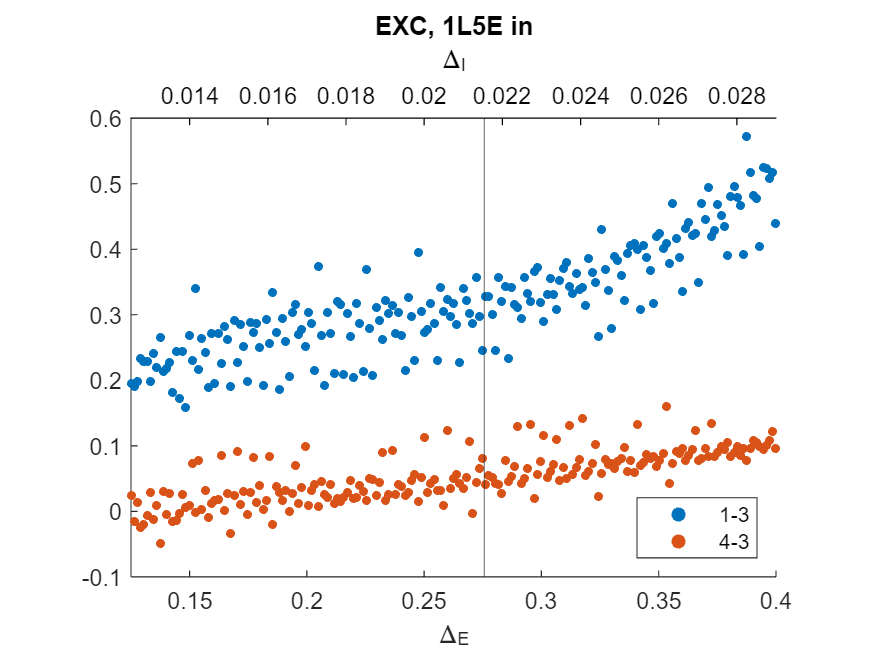

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 15;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    + squeeze(PET(:,pop,7,:)); %  + squeeze(PET(:,pop,7,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1);
y3 = exc(:,3);
y4 = exc(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("EXC, 1L5E in");

## EXC, 1L5E out

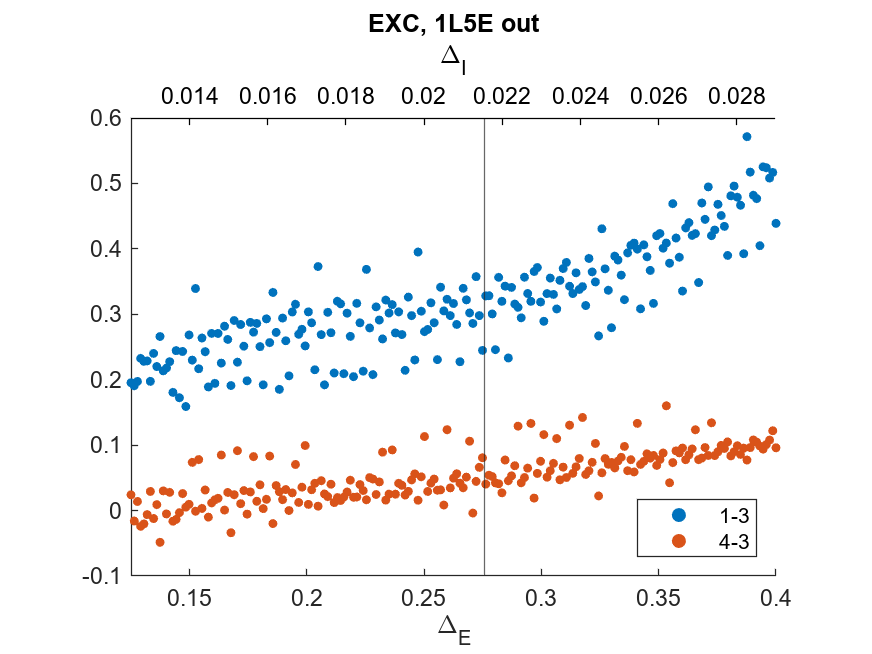

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 15;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); %  + squeeze(PET(:,pop,7,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1);
y3 = exc(:,3);
y4 = exc(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("EXC, 1L5E out");

## INH

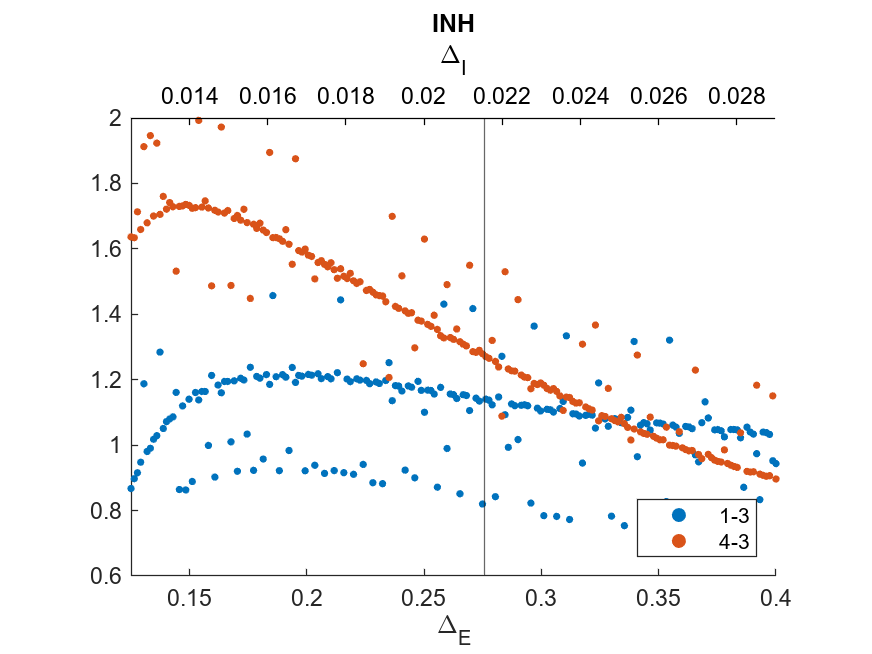

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 10;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) ...
     + squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

s = zeros(8,1);
ax1 = axes();

y1 = inh(:,1);
y3 = inh(:,3);
y4 = inh(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("INH");

## EXC+INH, 1L5E in

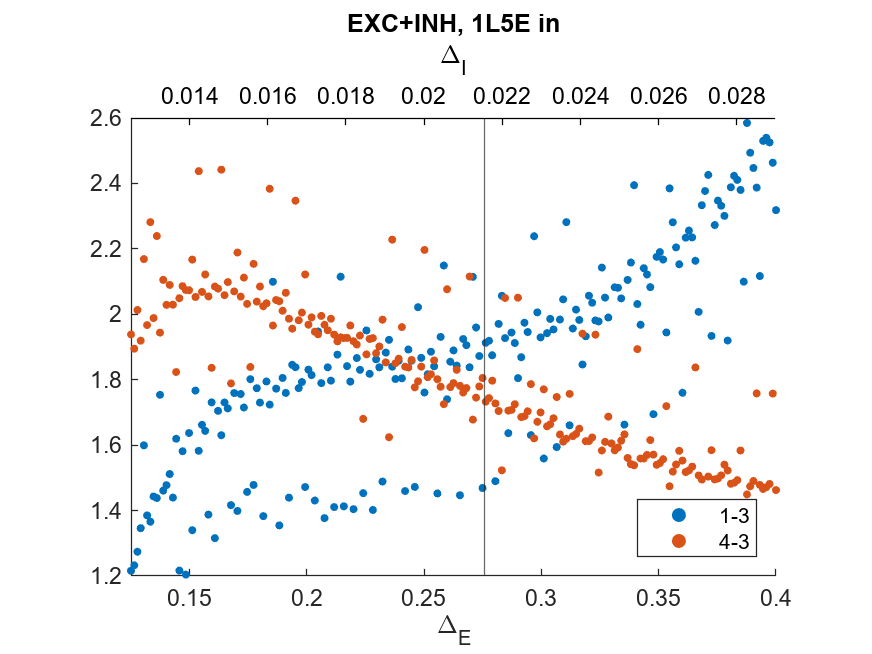

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 12;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:))  + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1) + inh(:,1);
y3 = exc(:,3) + inh(:,3);
y4 = exc(:,4) + inh(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("EXC+INH, 1L5E in");

## EXC+INH, 1L5E out

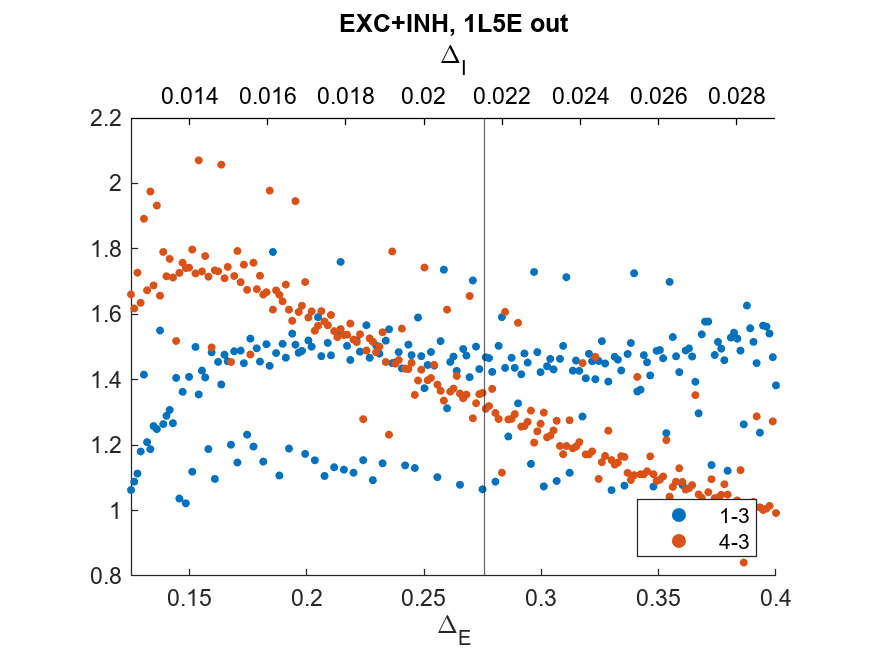

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 12;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); %  + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1) + inh(:,1);
y3 = exc(:,3) + inh(:,3);
y4 = exc(:,4) + inh(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("EXC+INH, 1L5E out");

## EXC - INH, 1L5E in

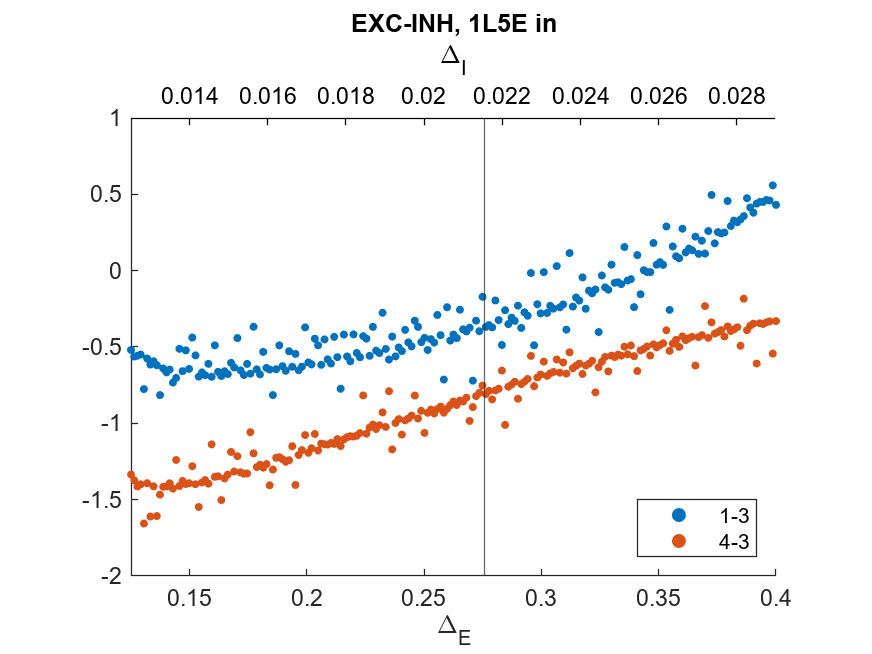

load data/0.125_0.4_0.0125_0.029_Iattn_0.02_201_4-10.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 12;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:))  + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1) - inh(:,1);
y3 = exc(:,3) - inh(:,3);
y4 = exc(:,4) - inh(:,4);

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [0 70];
legend([s1 s3],["1-3","4-3"], 'Location','southeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("EXC-INH, 1L5E in");

## tricks: only several essencial pathways

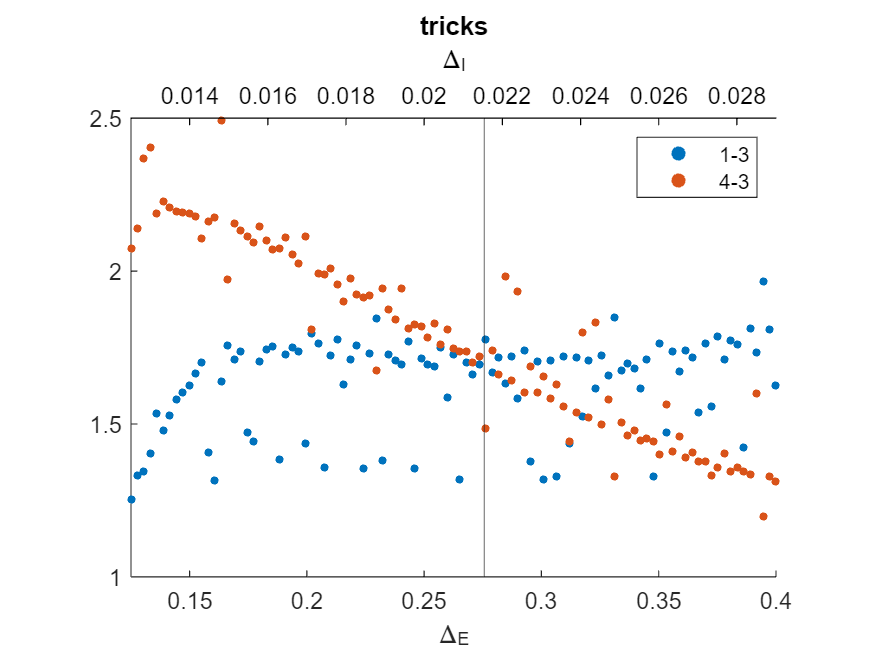

load data/0.125_0.4_0.0125_0.029_Iattn_0.02.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 12;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); %  + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1) + inh(:,1);
y3 = exc(:,3) + inh(:,3);
y4 = exc(:,4) + inh(:,4) + 0.15;

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y3,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [1 2.2];
legend([s1 s3],["1-3","4-3"], 'Location','northeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("tricks");

## cond1-cond3 EI, cond4-cond3 EI

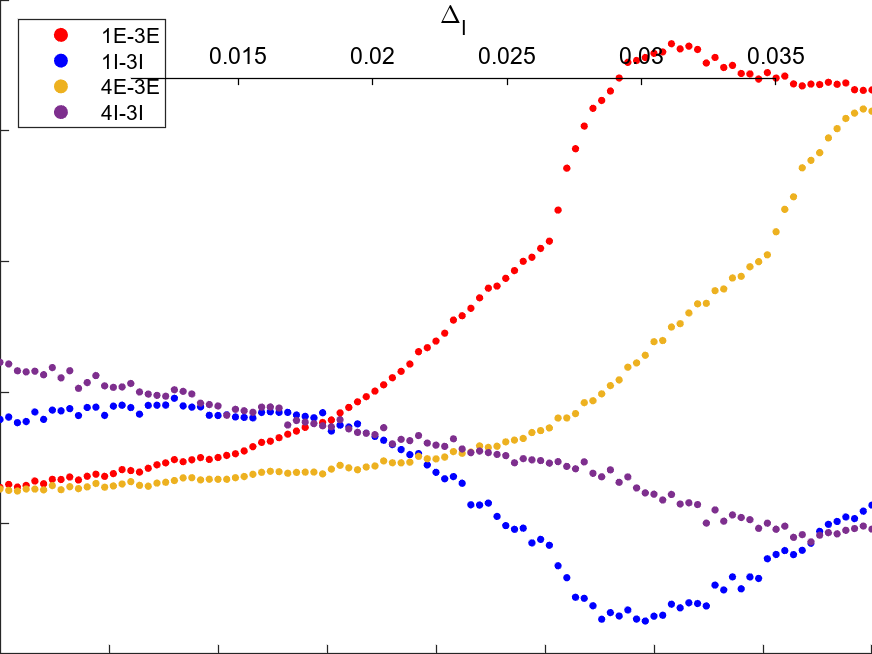

clear;
close all;
axlabels = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
pop = 5;
sz = 10;

load data/0.1_0.5_0.011_0.035_Iattn_0.04.mat;

startXbottom = 0.1; endXbottom = 0.5;
% lowY = 0; highY = 9;
x = linspace(startXbottom,endXbottom,size(PET,1));

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

diff13E = exc(:,1) - exc(:,3);
diff13I = inh(:,1) - inh(:,3);
diff43E = exc(:,4) - exc(:,3);
diff43I = inh(:,4) - inh(:,3);

figure();
ax1 = axes();
% recX = [startX 0.12 0.12 startX];
% recY = [lowY lowY highY highY];
% r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r1,0.1);
% 
% recX = [0.2275 endX endX 0.2275];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);

s1 = scatter(x, diff13E, sz, 'filled','r');
hold on
s2 = scatter(x, diff13I, sz, 'filled','b');
s3 = scatter(x, diff43E, sz, 'filled', 'MarkerFaceColor', "#EDB120");
s4 = scatter(x, diff43I, sz, 'filled', 'MarkerFaceColor', "#7E2F8E");

ax1.XLim = [startXbottom endXbottom];
% ax1.YLim = [40 110];
legend([s1 s2 s3 s4],["1E-3E", "1I-3I", "4E-3E", "4I-3I"], ...
    'Location','northwest');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.011 0.035];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.76];
set(ax1,'Position',pos);
set(ax2,'Position',pos);

% title("Energy transmitted in pathway");

## cond1: E-I, cond4: E-I

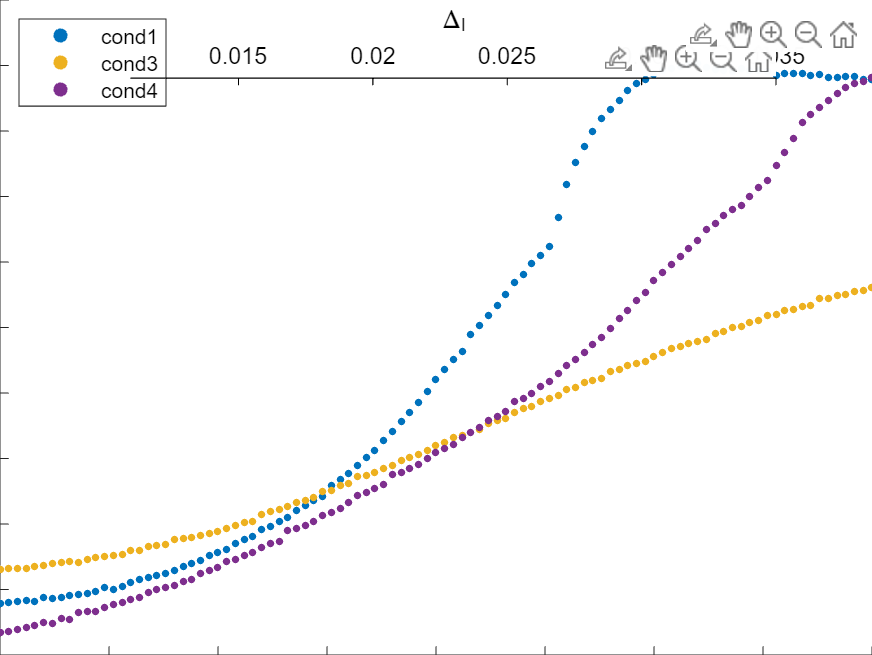

diffEI = exc - inh;

figure();
ax1 = axes();
% recX = [startX 0.12 0.12 startX];
% recY = [lowY lowY highY highY];
% r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r1,0.1);
% 
% recX = [0.2275 endX endX 0.2275];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);

s1 = scatter(x, diffEI(:,1), sz, 'filled', 'MarkerFaceColor', '#0072BD');
hold on
% s2 = scatter(x, diffEI(:,2), sz, 'filled', 'MarkerFaceColor', '#D95319');
s3 = scatter(x, diffEI(:,3), sz, 'filled', 'MarkerFaceColor', '#EDB120');
s4 = scatter(x, diffEI(:,4), sz, 'filled', 'MarkerFaceColor', '#7E2F8E');
% s5 = scatter(x, diffEI(:,5), sz, 'filled', 'MarkerFaceColor', '#77AC30');

ax1.XLim = [startXbottom endXbottom];
% ax1.YLim = [40 110];
legend([s1 s3 s4],["cond1", "cond3", "cond4"], ...
    'Location','northwest');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.011 0.035];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.76];
set(ax1,'Position',pos);
set(ax2,'Position',pos);

% title("Energy transmitted in pathway");


## one period

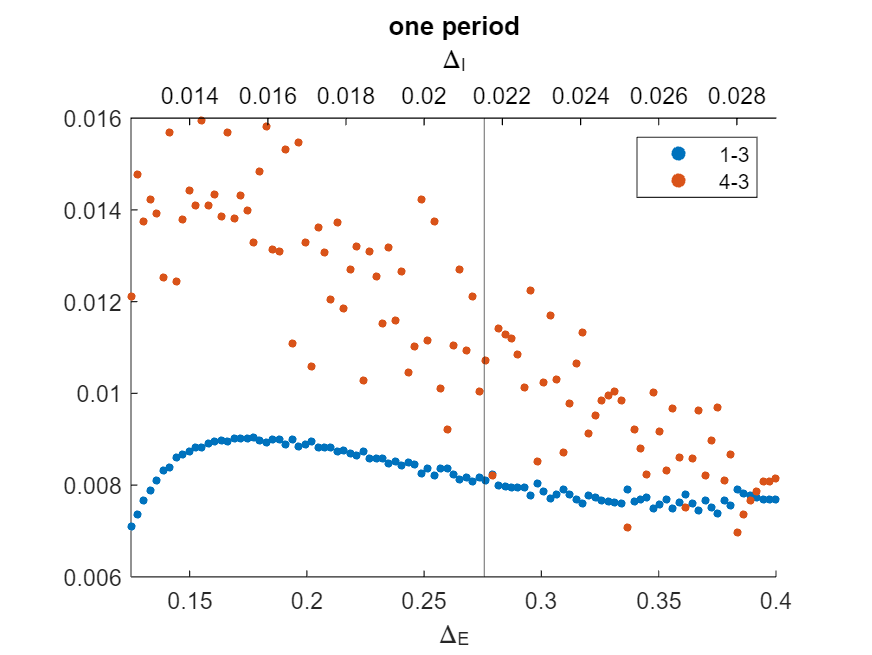

load data/onePrd_0.125_0.4_0.0125_0.029_Iattn_0.02.mat;
startXbottom = 0.125; endXbottom = 0.4; 
pop = 5; sz = 12;
x = linspace(startXbottom,endXbottom,size(PET,1));
figure();

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,6,:));

s = zeros(8,1);
ax1 = axes();

y1 = exc(:,1) + inh(:,1);
y3 = exc(:,3) + inh(:,3);
y4 = exc(:,4) + inh(:,4);% + 0.13;

s1 = scatter(x,y1 - y3,sz,'filled');
hold on;
s3 = scatter(x,y4 - y3,sz,'filled');
% s4 = scatter(x,y4,sz,'filled');
xline(oneRatio);

ax1.XLim = [0.125 0.4];
% ax1.YLim = [1 2.2];
legend([s1 s3],["1-3","4-3"], 'Location','northeast');

% handle second X-axis
ax2 = axes('Position', get(ax1,'Position'), ...
    'XAxisLocation','top', ...
    'Color','none', ...
    'XColor','k');
ax2.YAxis.Visible = 'off';
% ax2.XLim = ax1.XLim;
ax2.XLim = [0.0125 0.029];

xlabel(ax1, '\Delta_{E}');
xlabel(ax2, '\Delta_{I}');
% ylabel(ax1, "Energy (\muJ)");
pos = [0.15 0.12 0.74 0.7];
set(ax1,'Position',pos);
set(ax2,'Position',pos);
title("one period");